# Práctica 3. Métodos iterativos para sistemas lineales.

## Implementar los métodos de Jacobi y relajación para resolver de manera aproximada sistemas del tipo $Au=b$.

**a)** Para una matriz invertible $A$ de tamaño $n\times n$ y un vector $b$ de $n$ componentes, deseamos obtener la solución aproximada del sistema mediante iteración de Jacobi. Como argumentos extra, se pedirá una tolerancia, $tol$, y un número máximo permitido de iteraciones, $max \_ iter$, con los que crear un test de parada. Lo implementaremos en el **APÉNDICE A**.

La función nos debe devolver, dados $A$, $b$, $tol$, y $max\_ iter$:

- El vector $u$ de soluciones aproximadas.

- Si converge, el número de iteraciones $n\_ iter$ en el que ha llegado al residuo relativo admisible $tol$. Si no converge, un mensaje de error.

**b)** Para una matriz invertible $A$ de tamaño $n\times n$ y un vector $b$ de $n$ componentes, deseamos obtener la solución aproximada del sistema mediante el método de relajación con parámetro de relajación $w$. Como argumentos extra, se pedirá una tolerancia, $tol$, y un número máximo permitido de iteraciones, $max \_ iter$, con los que crear un test de parada. Lo implementaremos en el **APÉNDICE B**.

La función nos debe devolver, dados $A$, $b$, $w$, $tol$, y $max\_ iter$:

- El vector $u$ de soluciones aproximadas.

- Si converge, el número de iteraciones $n\_ iter$ en el que ha llegado al residuo relativo admisible $tol$. Si no converge, un mensaje de error.

- La norma del residuo absoluto, $r$.

**c)** A continuación, resuelve el siguiente sistema de forma aproximada mediante el método de Jacobi. Comprueba que la solución obtenida es lógica.

                                                      
$$\pmatrix{7 & 5 & 1 \cr 5 & 8 & 1\cr 1 & 1 & 3 } \, \vec{u} = \pmatrix{1 \cr 2 \cr 3}$$


A = [7,5,1;5,8,1;1,1,3];
b = [1;2;3];
tic
[u,n_iter] = iterJacobi(A,b,0.00001,10000);
toc

Elapsed time is 0.003765 seconds.


u

u =    -0.1591
    0.2273
    0.9773


n_iter

n_iter = 48

A\b

ans =    -0.1591
    0.2273
    0.9773


Ahora resuélvelo mediante el método de relajación con parámetro $w=1$ (Gauss-Seidel). Comprueba que la solución obtenida es lógica y compara el número de iteraciones con las necesarias por el método de Jacobi.

tic
[u,n_iter,~] = iterRelajacion(A,b,1,0.00001,10000);
toc

Elapsed time is 0.004814 seconds.


u

u =    -0.1591
    0.2273
    0.9773


n_iter

n_iter = 14


% El método de relajación ha requerido menos iteraciones
% posiblemente debido a que utiliza los nuevos resultados
% el momento en que se obtienen.

% Sin embargo, vemos que el tiempo que tarda Jacobi es menor
% puede deberse a que admite paralelismo o que el tiempo por
% iteracion sea menor.

**d)** Por último, resuelve el sistema dado por $A$ y $b$ en 'variables2.mat' mediante el método de relajación para parámetros $w=0.1:0.1:1.9$. Rellena el código para obtener dos gráficas que muestren el número de iteraciones y el residuo relativo con respecto a $w$. ¿Qué valor de $w$ crees que ha sido el mejor para resolver este sistema? Justifícalo en un comentario.

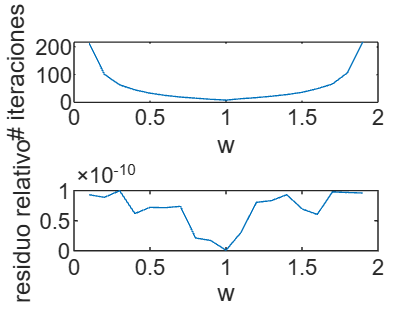

%Utiliza estos parámetros
w=0.1:0.1:1.9;
tol=1e-10;
max_iter=250;

%Escribe aquí tu código
load("variables2.mat");
iteraciones = zeros(length(w),1);
residuos_absolutos = zeros(length(w),1);
for i = 1:length(w)
[~,iteraciones(i),residuos_absolutos(i)] = iterRelajacion(A,b,w(i),tol,max_iter);
end
residuos_relativos = residuos_absolutos / norm(b,Inf);


%Rellena los plots con las variables adecuadas.
subplot(2,1,1)
plot(w,iteraciones)
xlabel('w')
ylabel('# iteraciones')
subplot(2,1,2)
plot(w,residuos_relativos)
xlabel('w')
ylabel('residuo relativo')


% El mejor valor es w = 1, ya que se obtiene el
% mínimo tanto de iteraciones como de residuo entre
% los datos estudiados

### Apéndice A. Método de Jacobi

function [u,n_iter]=iterJacobi(A,b,tol,max_iter)

%Comprobar convergencia. Diagonalmente dominante por filas 
if all((2*abs(diag(A))) <= sum(abs(A),2))
    disp("No es diagonalmente dominante. No se puede asegurar que sea convergente.");
    return;
end 

N = size(A,1);
n_iter = 0;
r = Inf;
d = zeros(N,1);
u = zeros(N,1);
norma_b_tol = norm(b, Inf) * tol; 
while(n_iter <= max_iter && norm(r, Inf) >= norma_b_tol)
    r = b - A*u;
    d = r ./ diag(A);
    u = u + d;
    n_iter = n_iter + 1;
end

end

### Apéndice B. Método de relajación

function [u,n_iter,rn]=iterRelajacion(A,b,w,tol,max_iter)

%comprobamos convergencia
if w <= 0 || w >= 2 
    disp("No es convergente.");
    return;
elseif ~ishermitian(A) || ~all(eig(A) > 0)
    disp("No se puede asegurar que sea convergente.");
    return
end 

N = size(A,1);
assert(N == size(A,2) && N == length(b), "las dimensiones no coinciden");
r = zeros(N,1);
d = zeros(N,1);
u_anterior = zeros(N,1);
u = zeros(N,1);
tol_norma_b = tol * norm(b,Inf);

for n_iter = 1:max_iter
    for i = 1:N
        r(i) = b(i) - A(i, 1:i-1) * u(1:i-1) - A(i, i:N) * u_anterior(i:N);
        d(i) = w * r(i) / A(i, i);
        u(i) = u_anterior(i) + d(i);
    end
    u_anterior = u;
    if norm(r,Inf) < tol_norma_b
        rn = norm(r, Inf);
        break;
    end
end

rn = norm(r,Inf);   
end